## JK - Robot Visualizer Example: Maps and Lidar

Jeremie Kahan - Copyright 2018 The MathWorks, Inc.

Create a map without trajectory display. The map should be a valid [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid) object.

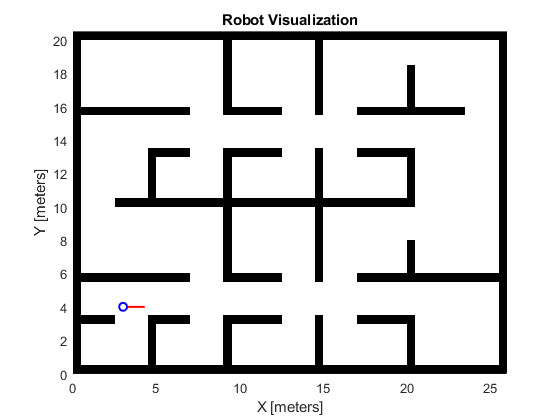

% Base map


viz = Visualizer2D;
viz.showTrajectory = false;
load complexMap
viz.mapName = 'map';
pose = [3; 4; 0];
viz(pose)

Spin the robot in place, simulate the lidar sensor, and view the results.

**NOTE:** If you run this section in a plain code script, this section will be animated.

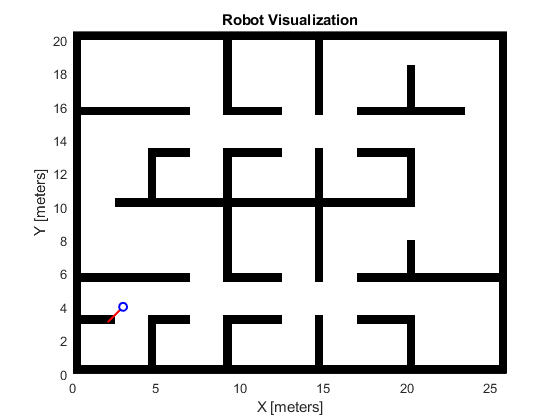

for idx = 1:10
    pose = pose + [0; 0; pi/8];
    ranges = lidar(pose);
    viz(pose)
    pause(0.25)
end